# Data visualization tutorial for COCOAN101-L13

by Choong-Wan (Wani) Woo

## 1. Run some of the analyses (one sample t-test) from L04 example code

% key functions: fmri_data, plot

basedir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/COCOAN101/L04';
% datdir = fullfile(basedir, 'example_data/bmrk3_temp_avg');
datdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/R_advancedfmri/advancedfmrianalysis2_2020spring/tutorials/wani_session/example_data/bmrk3_temp_avg';

imgs = filenames(fullfile(datdir, 'sub*heat*nii'));

% dat = fmri_data(imgs);
% default mask: >> which('brainmask_canlab.nii')
% or you can also use different masks, e.g., 

dat_gray = fmri_data(imgs, which('gray_matter_mask.nii'));

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 154924704 bytes
Loading image number:   198
경과 시간은 2.310719초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 31852256  Bit rate: 24.92 bits


tdat = ttest(dat_gray, 0.05, 'bfr');

One-sample t-test
Calculating t-statistics and p-values

Image   1
 51 contig. clusters, sizes   1 to 12942
Positive effect: 29884 voxels, min p-value: 0.00000000
Negative effect: 23179 voxels, min p-value: 0.00000000


prune_dat = pruning_img(tdat, [.05 .001 .05/numel(tdat.p)], [1 1 10]);
dat.fullpath = fullfile(datdir, 'prune_temp_avg_05_001_bfr.nii');
write(dat);

## 2. brain_activation_display.m in CocoanCORE

Recently upgraded from brain_activations_wani.m 

Please use brain_activations_display, not _wani.m 

Grouping contiguous voxels:  51 regions
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_right', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
___________________________________________
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_left', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
___________________________________________
Load underlay. Define axes. Ready. 
Load underlay. Define axes. Ready. 
Load underlay. Define axes. Ready. 
Load underlay. Define axes. Ready. 
Load underlay. 

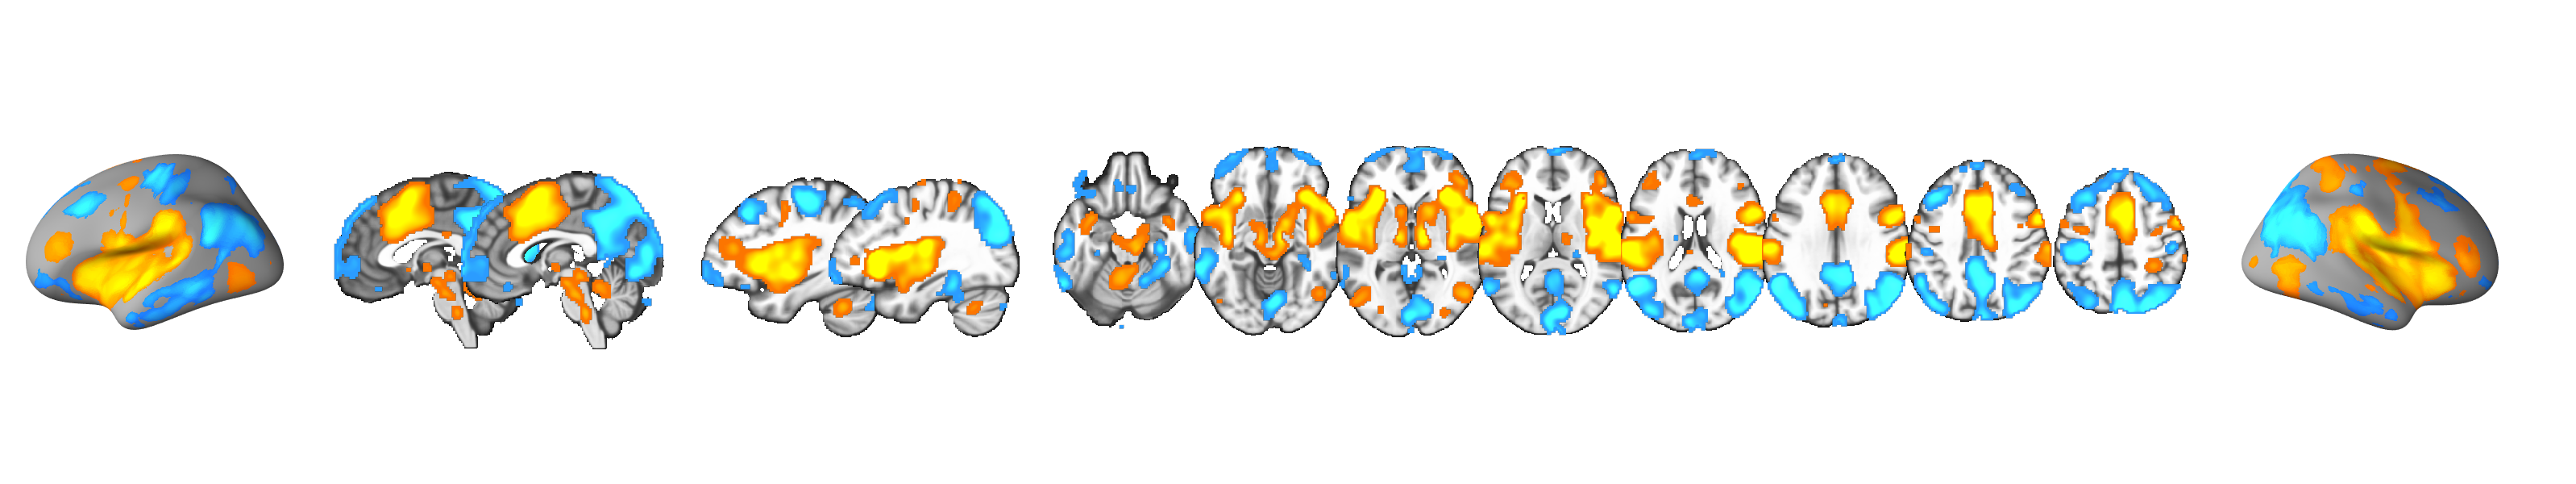

close all;
% you need this to use brain_activations_display: https://github.com/cocoanlab/cocoanCORE

[out, o2] = brain_activations_display(region(tdat));

help brain_activations_display

  This function diplay brain activations on a inflated brain and few 
  saggital, axial slices. Cocoan style activation visualization.
 
  :Usage:
  ::
 
     [out, o2] = brain_activations_display(cl, varargin)
 
  :Inputs:
 
    **r:**
         region object/activation map
 
  :Optional Inputs:
 
    **inflated:**
         not recommended
         use inflated brain. We use the 32k inflated brain surface from HCP
         connectome workbench. (Q1-Q6_R440.R.inflated.32k_fs_LR.surf.gii and 
         Q1-Q6_R440.L.inflated.32k_fs_LR.surf.gii)
 
    **very_inflated (default):**
         recommended
         use freesurfer inflated brain with Thomas Yeo group's RF_ANTs mapping
         from MNI to Freesurfer. (https://doi.org/10.1002/hbm.24213)
 
    **very_inflated_workbench:**
         use very inflated brain. We also use the 32k inflated brain surface 
         from HCP connectome workbench. 
         (Q1-Q6_R440.R.very_inflated.32k_fs_LR.surf.gii and 
          Q1-Q6_R440.L.very_inflat

Grouping contiguous voxels:  51 regions
***************************************************************************************************************
You selected to 'all2' option. It will draw four sagittal slices and six axial slices with two surface maps.
If you want to specify x and z for sagittal and axial slices, you can use 'all2_xyz' option.
E.g., 'all2_xyz', [-5 2 -35 35 -30:12:60], first four will be used as x's and the six numbers after that
      will be used as z. More than 10 numbers will be ignored.
***************************************************************************************************************
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_right', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
_________

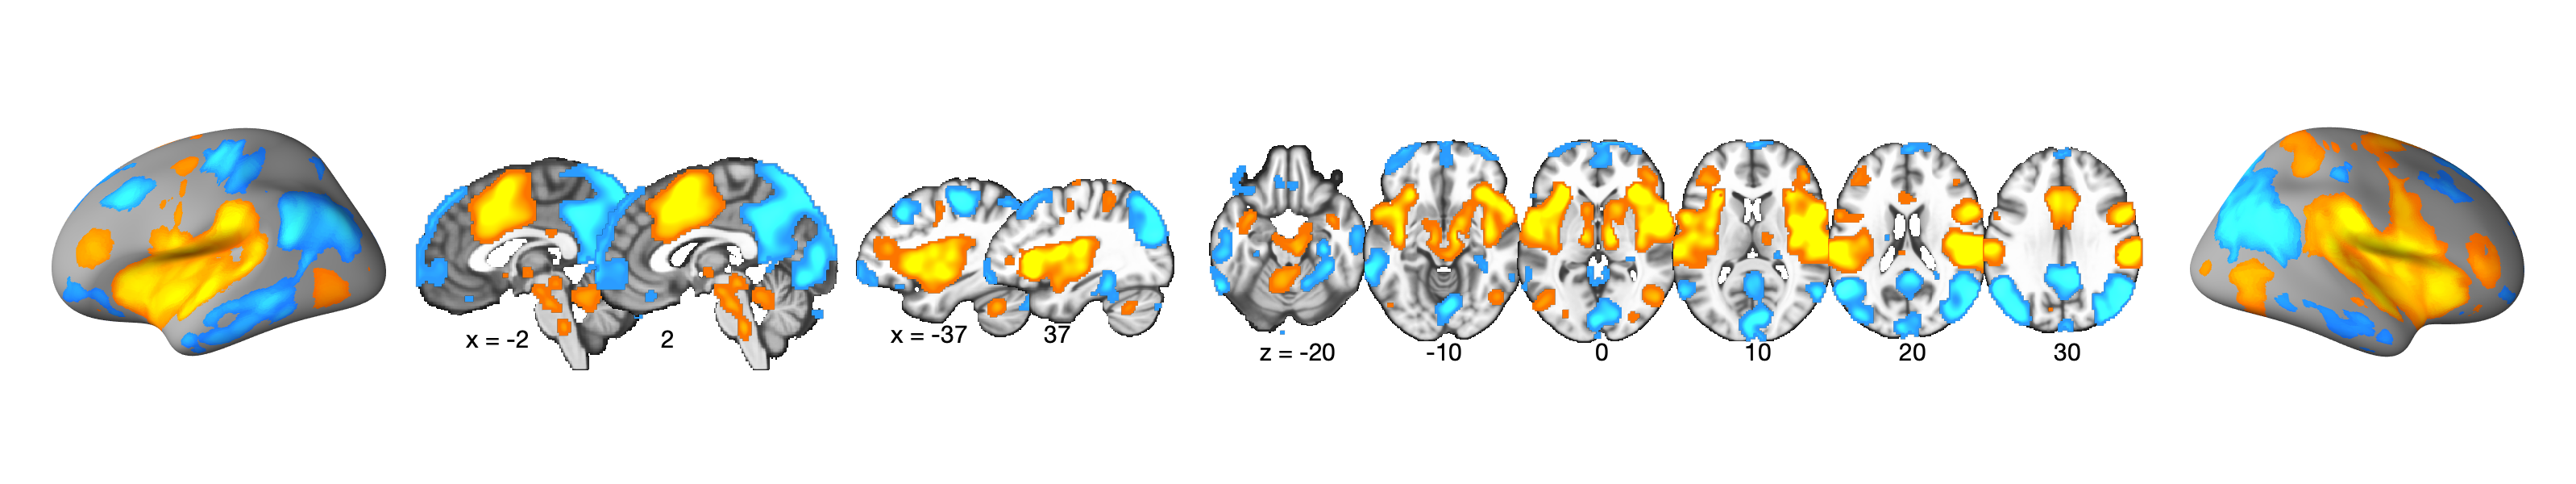

% 'all2' option: close to publication-level brain figure
close all;
[out, o2] = brain_activations_display(region(tdat), 'all2', 'labels');

Grouping contiguous voxels:  51 regions
***************************************************************************************************************
You selected to 'all2' option. It will draw four sagittal slices and six axial slices with two surface maps.
If you want to specify x and z for sagittal and axial slices, you can use 'all2_xyz' option.
E.g., 'all2_xyz', [-5 2 -35 35 -30:12:60], first four will be used as x's and the six numbers after that
      will be used as z. More than 10 numbers will be ignored.
***************************************************************************************************************
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_right', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
_________

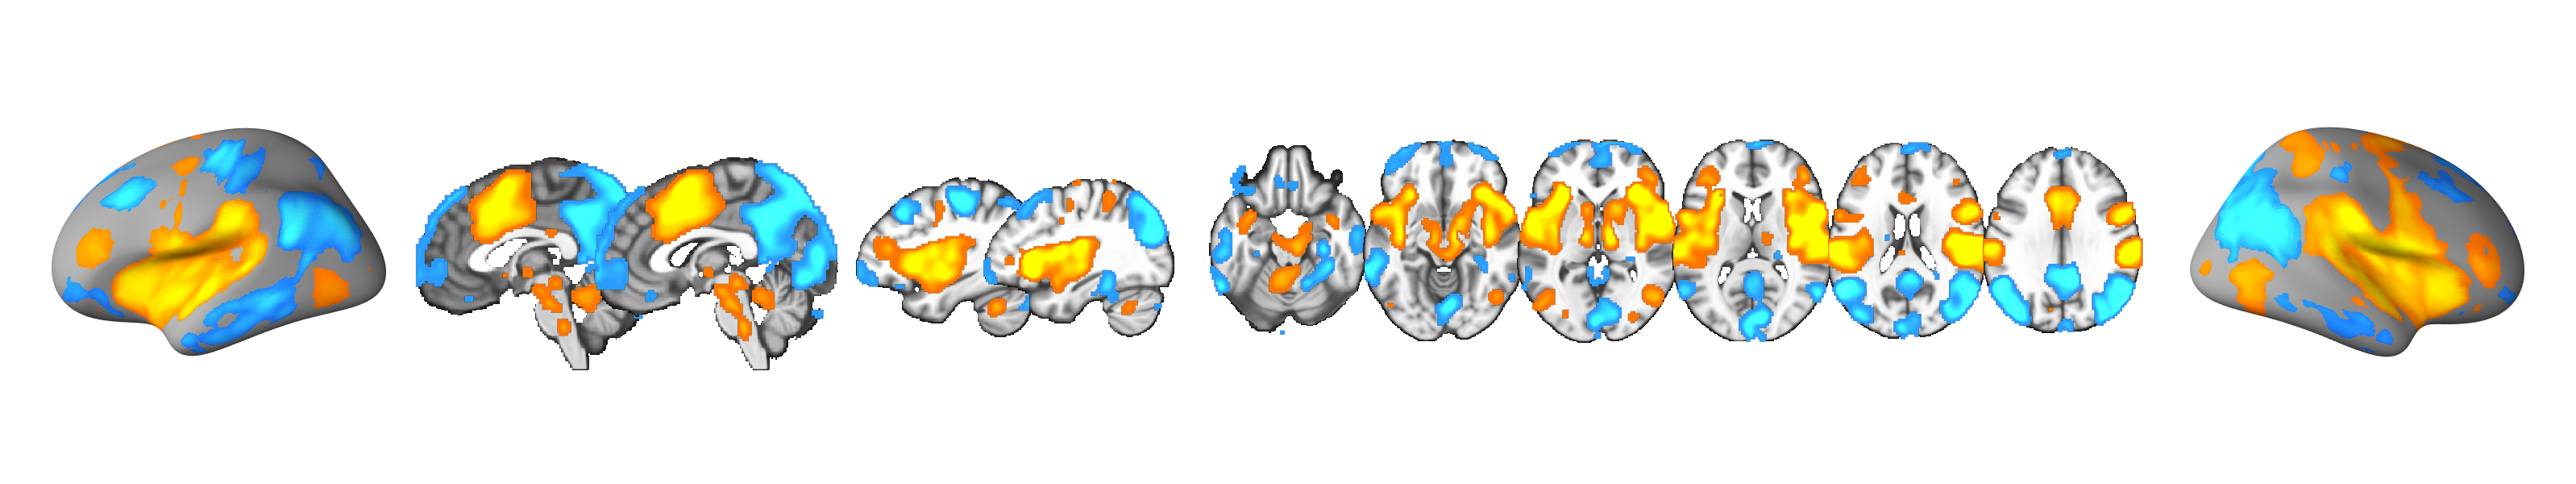

close all;
[out, o2] = brain_activations_display(region(tdat), 'all2');

Grouping contiguous voxels:  51 regions
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_left', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
___________________________________________
Using custom color maps.
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors_cocoan(xyz, p, mycolors, [.5 .5 .5], 3,'colorscale',actcolors,'fsavg_right', 'prioritize_last');
Main color vertices: 163842 vertices.  selecting: 53063
Calculating distance...
Finished!
___________________________________________


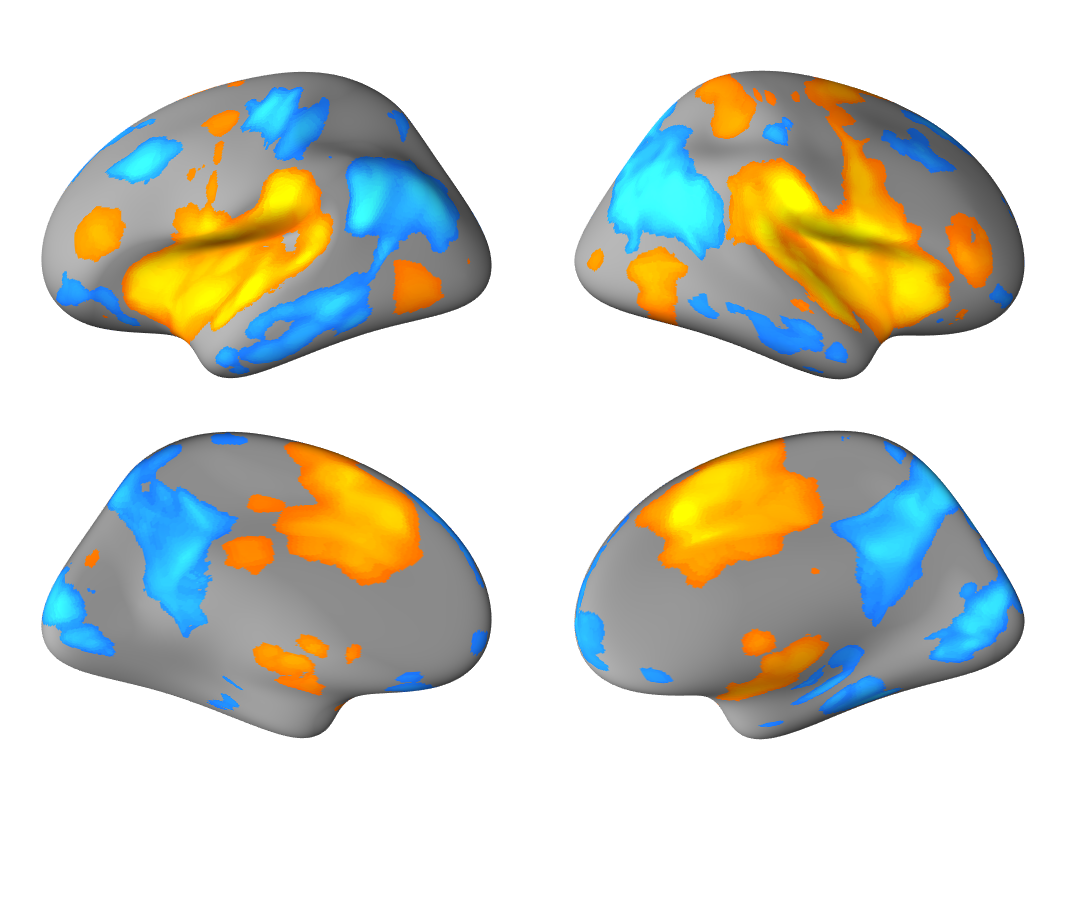

% 'surface_only', 'surface_all'
close all;
[out, o2] = brain_activations_display(region(tdat), 'surface_only', 'surface_all');

## 3. glass_brain_network.m in CocoanCORE

r = region(tdat);

Grouping contiguous voxels:  51 regions


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.
 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.
 Running color change.


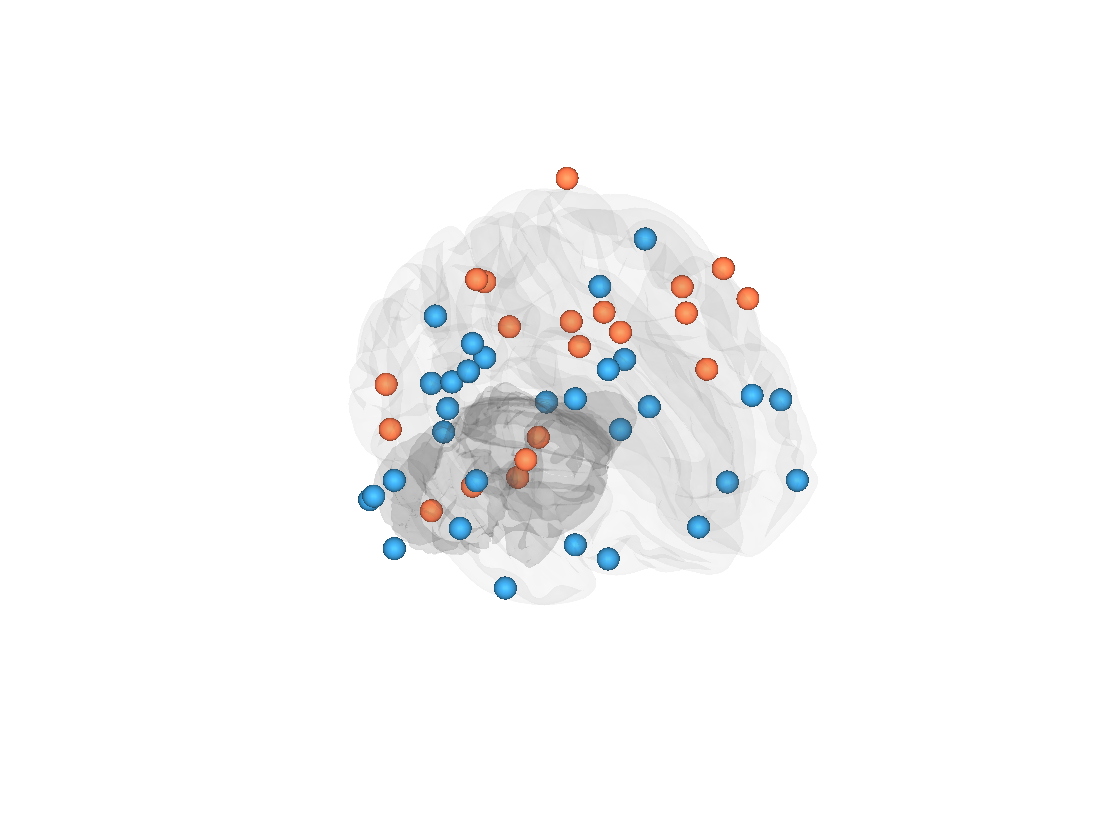


for i = 1:numel(r)
    rsign(i,1) = sign(r(i).Z(1));
end

cluster_idx = double(rsign==-1) + double(rsign==1)*2;
cols = [0.1961    0.5333    0.7412;
    0.9569    0.4275    0.2627];
close all;
h = glass_brain_network(r, 'group', cluster_idx, 'colors', cols, 'radius', 4, 'sphere');

basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.
 Running color change.


basecolor =     0.5000    0.5000    0.5000


Main color vertices: Coords is empty. Nothing to plot.
 Running color change.


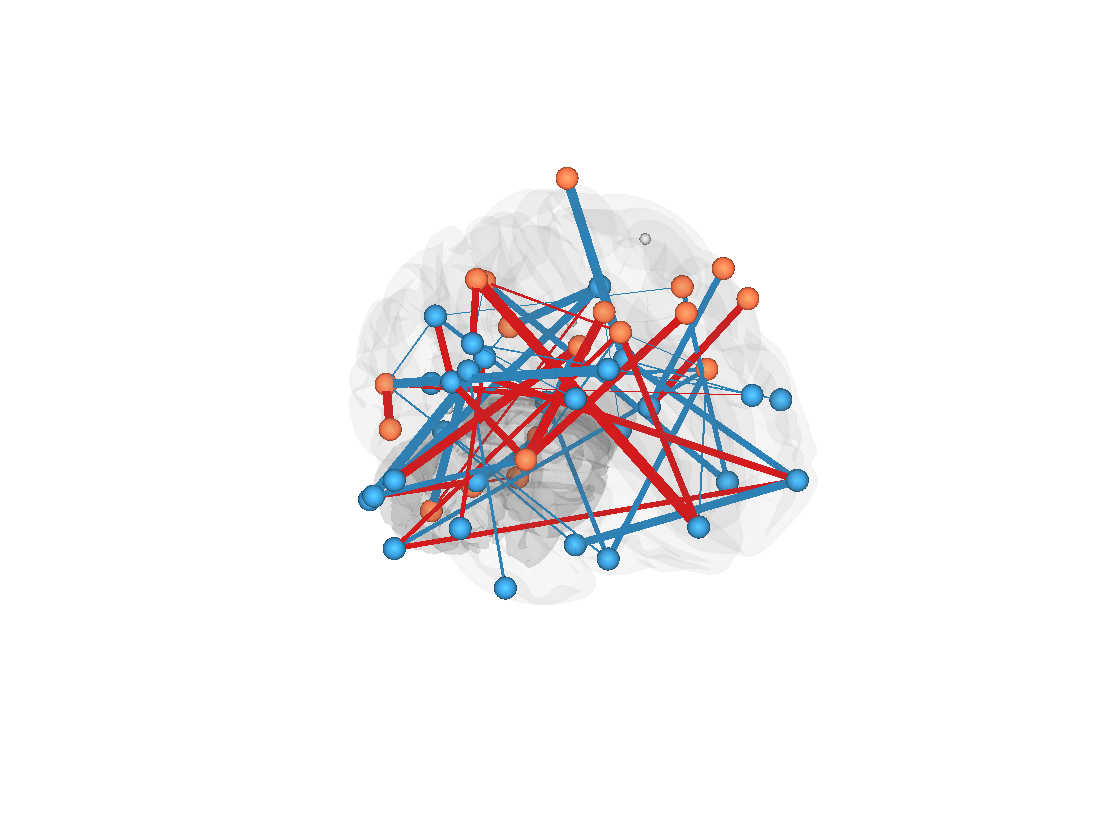

% create a random positive and negative weights
w = rand(numel(r));
w = rand(numel(r)) .* (double(w>0.993)-double(w<0.007));
w = reformat_r_new(w, 'symmetric_sum');
close all;
h = glass_brain_network(r, 'group', cluster_idx, 'colors', cols, 'sphere', 'edge_weights', w, 'hl_node_edge', 4, 2, [.7 .7 .7]);

## 4. boxplot_wani_2016.m

% mask atlas: CANlab_combined_atlas_object_2018.mat
% key functions: select_atlas_subset, 
% apply_mask or extract_roi_averages

load(which('CANlab_combined_atlas_object_2018.mat'));
thal = select_atlas_subset(atlas_obj, {'Thal'});
nac = select_atlas_subset(atlas_obj, {'NAC'});
amyg = select_atlas_subset(atlas_obj, {'Amygdala'});

thal = remove_empty(thal);
nac = remove_empty(nac);
amyg = remove_empty(amyg);

dat_thal = apply_mask(dat_gray, thal);
dat_nac = apply_mask(dat_gray, nac);
dat_amyg = apply_mask(dat_gray, amyg);


% key functions: ttest, plot_specificity_box
temp_idx = repmat((1:6)', 1, 33);
temp_idx = temp_idx(:);

dat_thal_heatlv2 = dat_thal.dat(:, temp_idx==2);
dat_thal_heatlv5 = dat_thal.dat(:, temp_idx==5);

dat_nac_heatlv2 = dat_nac.dat(:, temp_idx==2);
dat_nac_heatlv5 = dat_nac.dat(:, temp_idx==5);

dat_amyg_heatlv2 = dat_amyg.dat(:, temp_idx==2);
dat_amyg_heatlv5 = dat_amyg.dat(:, temp_idx==5);


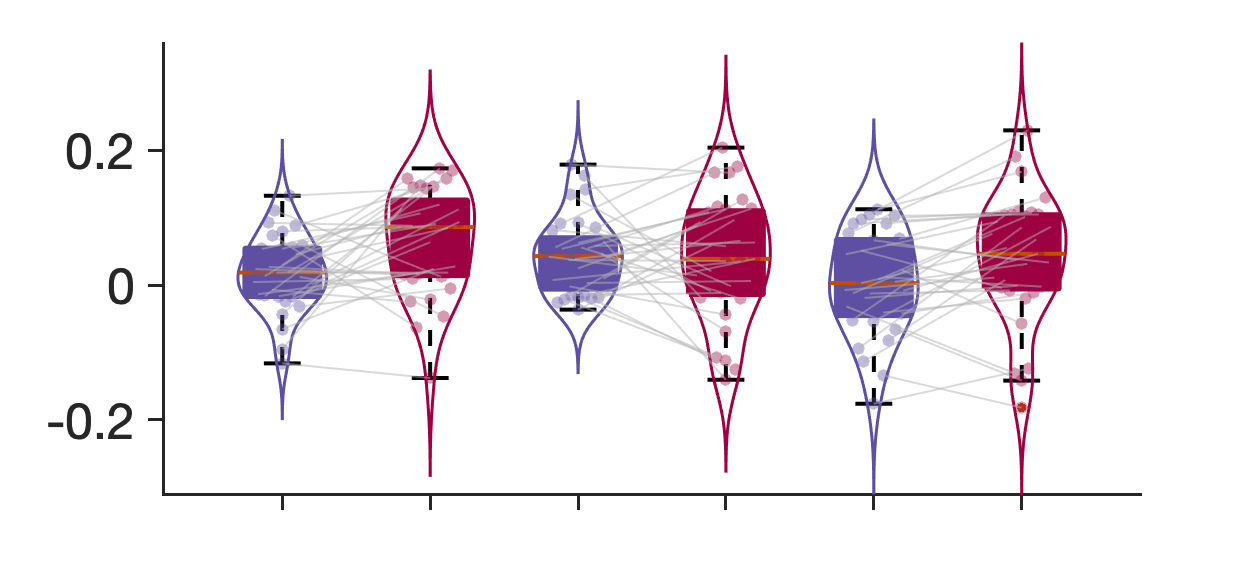


x = [mean(dat_thal_heatlv2)' mean(dat_thal_heatlv5)' mean(dat_nac_heatlv2)' mean(dat_nac_heatlv5)' mean(dat_amyg_heatlv2)' mean(dat_amyg_heatlv5)'];

col =  [0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588
    0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588
    0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588];

close all;
[handles, dot_locs] = boxplot_wani_2016(x, 'color', col, 'linewidth', 2, 'boxlinewidth', 3, 'violin', 'dots');
for i = 1:2:5
    hold on; 
    line([dot_locs.x{i} dot_locs.x{i+1}]' , [dot_locs.y{i} dot_locs.y{i+1}]', 'linewidth', 1, 'color', [.7 .7 .7 .5]);
end

drawnow; close all;


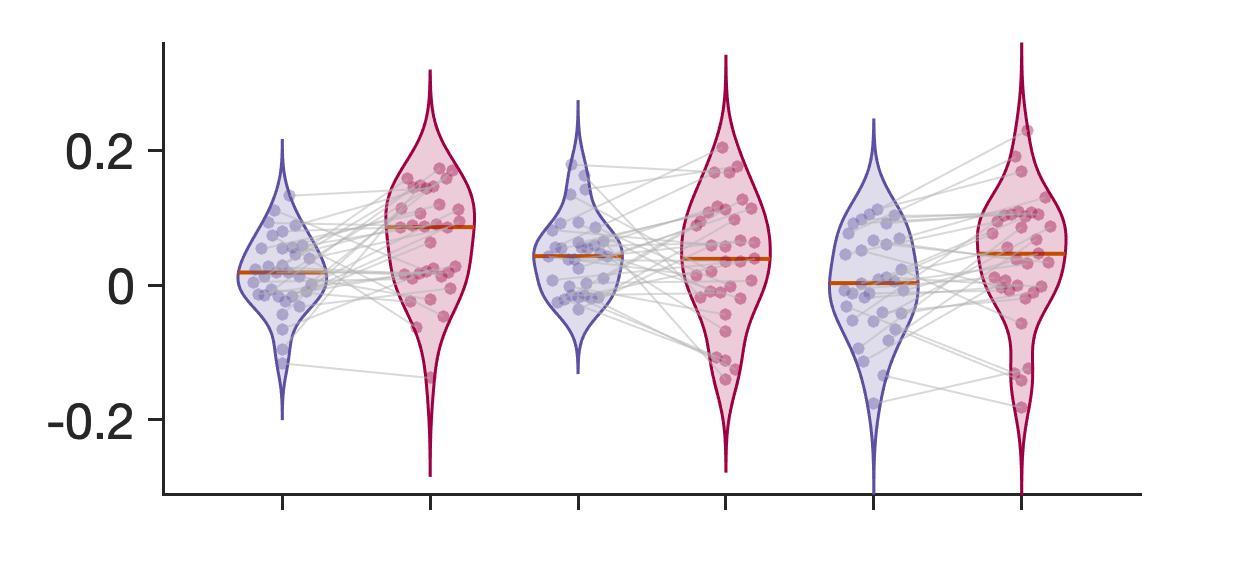

% only violin
x = [mean(dat_thal_heatlv2)' mean(dat_thal_heatlv5)' mean(dat_nac_heatlv2)' mean(dat_nac_heatlv5)' mean(dat_amyg_heatlv2)' mean(dat_amyg_heatlv5)'];

col =  [0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588
    0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588
    0.3686    0.3098    0.6353
    0.6196    0.0039    0.2588];

close all;
[handles, dot_locs] = boxplot_wani_2016(x, 'color', col, 'linewidth', 2, 'boxlinewidth', 3, 'violin', 'dots', 'nobox', 'violin_alpha', .2);
for i = 1:2:5
    hold on; 
    line([dot_locs.x{i} dot_locs.x{i+1}]' , [dot_locs.y{i} dot_locs.y{i+1}]', 'linewidth', 1, 'color', [.7 .7 .7 .5]);
end

drawnow; close all;

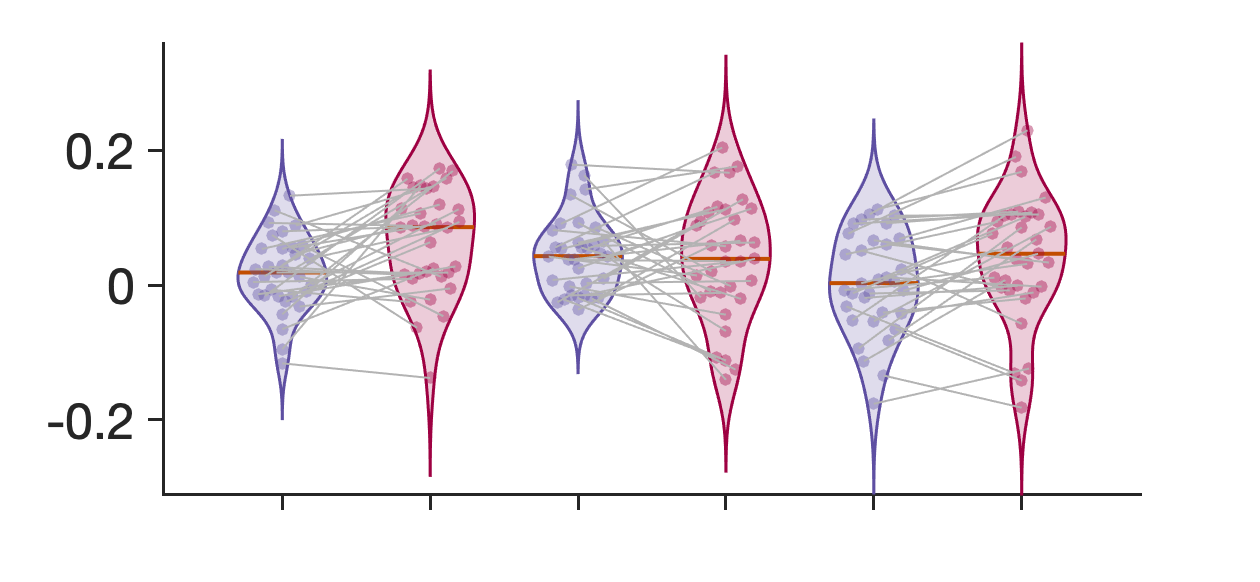

% how to save this as PDF run this again in the command window
close all;
[handles, dot_locs] = boxplot_wani_2016(x, 'color', col, 'linewidth', 2, 'boxlinewidth', 3, 'violin', 'dots', 'nobox', 'violin_alpha', .2);
for i = 1:2:5
    hold on; 
    line([dot_locs.x{i} dot_locs.x{i+1}]' , [dot_locs.y{i} dot_locs.y{i+1}]', 'linewidth', 1, 'color', [.7 .7 .7 .5]);
end

figdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/COCOAN101/L13';
savename = fullfile(figdir, 'boxviolinplot.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## 5. plot_specificity_box.m

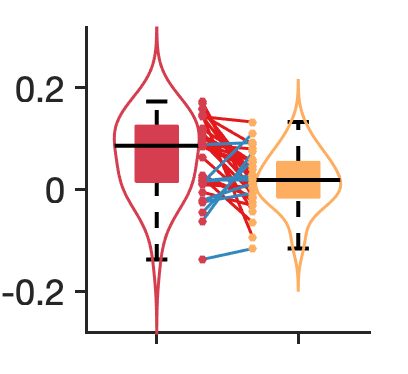

[h, p, ci, tstat] = ttest((mean(dat_thal_heatlv5)-mean(dat_thal_heatlv2))');

out = plot_specificity_box(mean(dat_thal_heatlv5)', mean(dat_thal_heatlv2)');

% save PDF
close all;
out = plot_specificity_box(mean(dat_thal_heatlv5)', mean(dat_thal_heatlv2)');
figdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/COCOAN101/L13';
savename = fullfile(figdir, 'plotspecificity.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


## 6. sepplot.m

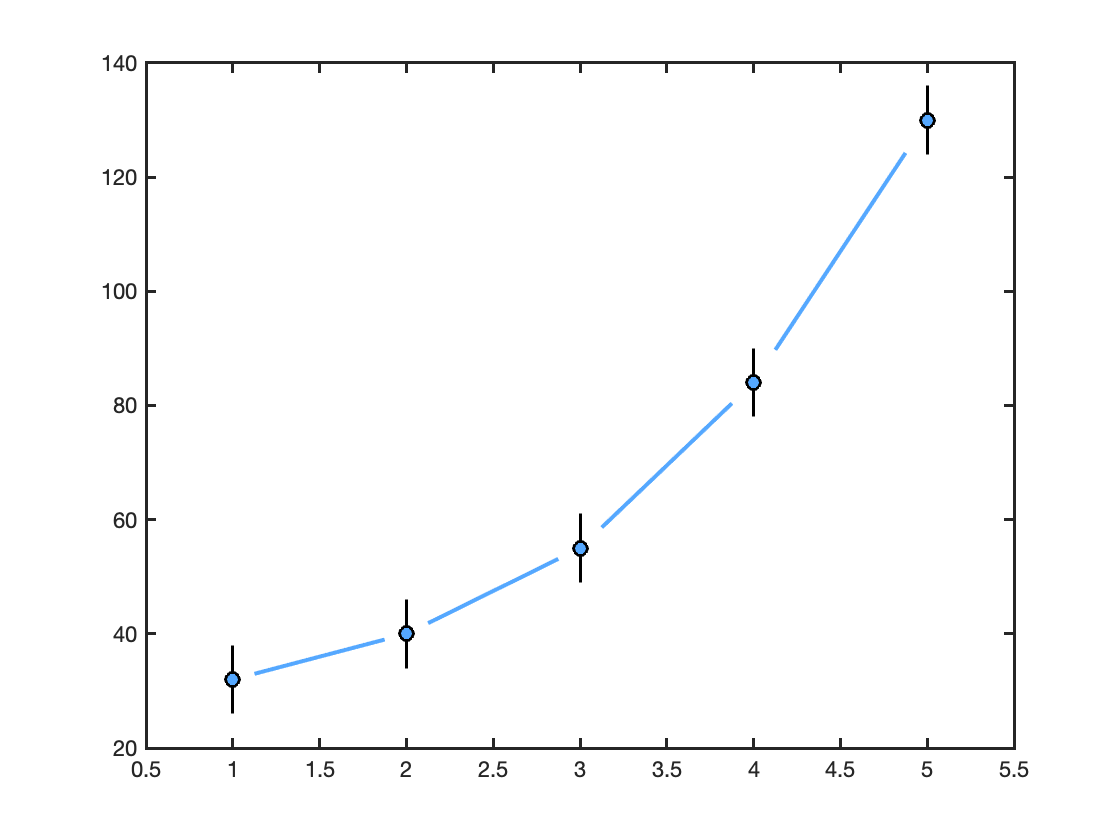

x = 1:5; % x values
y = [32 40 55 84 130]; % mean
e = [6 6 6 6 6]; % standard error of the mean

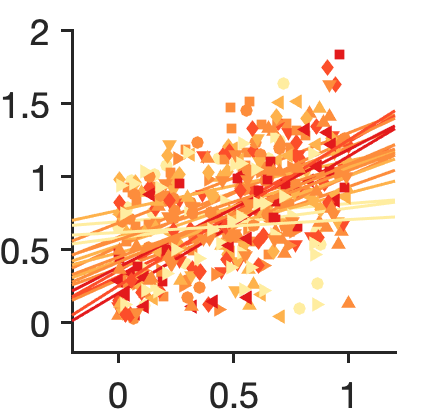


col = [0.3333    0.6588    1.0000];
markercol = col-.2;

close all; 
h = errorbar(x, y, e, 'o', 'color', 'k', 'linewidth', 1.5, 'markersize', 7, 'markerfacecolor', col);
hold on;
sepplot(x, y, .75, 'color', col, 'linewidth', 2);
h.CapSize = 0;


set(gca, 'xlim', [.5 5.5], 'linewidth', 1.5);

## 7. plot_y_yfit.m

% create fake data
for i = 1:20
    yval{i} = rand(20,1);
    yfit{i} = yval{i}.*rand(20,1) + rand(20,1);
end
out = plot_y_yfit(yval, yfit, 'xlim', [-0.2 1.2], 'ylim', [-0.2 2]);
% save PDF
% figdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/COCOAN101/L13';
% savename = fullfile(figdir, 'plotyyfit.pdf');
% 
% pagesetup(gcf);
% saveas(gcf, savename);
% 
% pagesetup(gcf);
% saveas(gcf, savename);